# Pràctica MATLAB Processament d'imatges (GRUP 2)

**Noms:  Adriana Avilés, Anna Garcia, David Morillo, Paula Franco                        **

**Grup: 9**

**NIUs: 1676127, 1665817, 1666540, 1674234**

Aquesta pràctica està dissenyada per ajudar-te a familiaritzar-te amb l'entorn de MATLAB per al processament d'imatges. Tindràs l'oportunitat de comprendre com aplicar tècniques de millora d'imatges a través del programari. Aquesta experiència t'oferirà una base sòlida per a futures tasques d'anàlisi i processament d'imatges utilitzant MATLAB.

**Lectura i Visualització d'Imatges:**

Llegeix la imatge de l'arxiu "manzana.jpg"  i mostra-la a la pantalla.

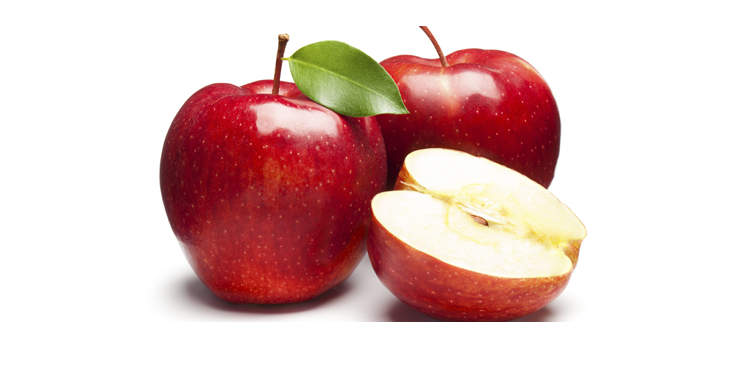

%Llegeix i visualitza la imatge
imatge_rgb = imread('manzana.jpg');
figure;
imshow(imatge_rgb)

**Conversió a escala de grisos:**

Dissenya la funció *im_escala_grisos* que rep com a paràmetres la imatge llegida anteriorment i la converteix a escala de grisos utilitzant la fórmula de luminància (0.299*R + 0.587*G + 0.114*B, on R, G i B són els valors dels píxels en els canals vermell, verd i blau, respectivament). Mostra la imatge en escala de grisos a la pantalla.

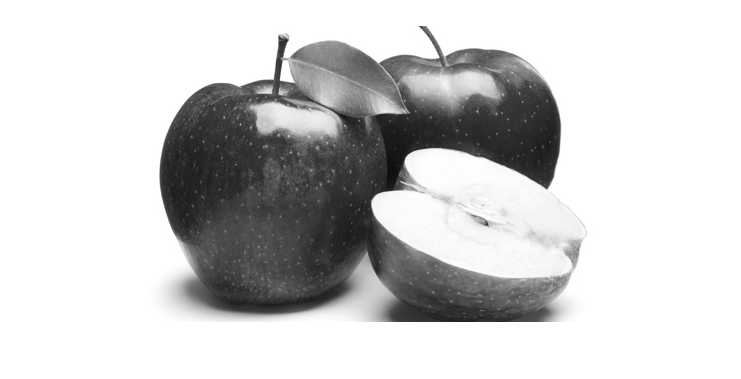

function imatge_grisos = im_escala_grisos(imatge)
    % Obtenim les dimensions de la imatge
    [files, columnes, canals] = size(imatge);
    
    % Inicialitzem la matriu de la img gris
    imatge_grisos = zeros(files, columnes);
    
    % Utiliztem la fòrmula
    for i = 1:files
        for j = 1:columnes
            imatge_grisos(i, j) = 0.299 * imatge(i, j, 1) + 0.587 * imatge(i, j, 2) + 0.114 * imatge(i, j, 3);
        end
    end
    imatge_grisos = uint8(imatge_grisos);
end

imatge_gris = im_escala_grisos(imatge_rgb);
% Mostrar la imatge
figure;
imshow(imatge_gris)

**Filtrat d'Imatges:**

Implementa manualment un filtre de mitjana sobre la imatge en escala de grisos. Utilitza una matriu de 5x5 per a la convolució. Mostra la imatge filtrada a la pantalla.

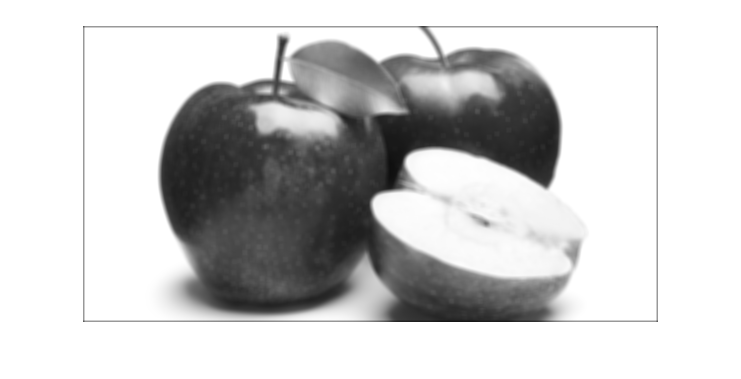

function im_filtered_mean = apply_mean_filter(im_grayscale)
    % Filtre de mitjana
    mean_filter = fspecial('average', [5 5]);
    % Aplicar el filtre
    im_filtered_mean = imfilter(im_grayscale, mean_filter);
end

imatge_avg = apply_mean_filter(imatge_gris);
figure;
imshow(imatge_avg)

**Filtrat d'Imatges (2):**

Implementa manualment un filtre de mediana sobre la imatge en escala de grisos. Utilitza una matriu de 5x5 per a la convolució. Mostra la imatge filtrada a la pantalla.

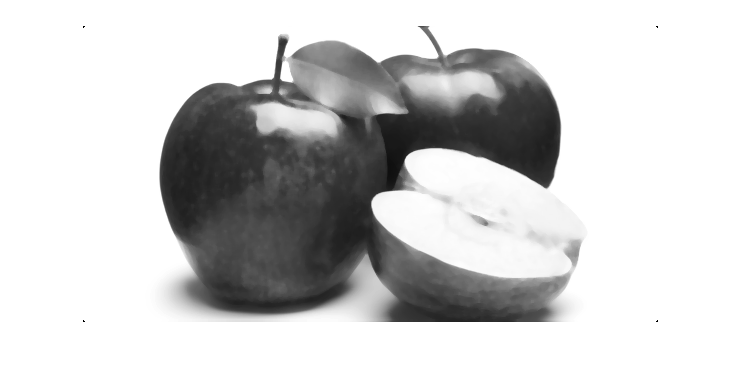

function im_filtered_median = apply_median_filter(im_grayscale)
    % Filtre de mediana amb una matriu de 5x5
    im_filtered_median = medfilt2(im_grayscale, [5 5]);
end

imatge_med = apply_median_filter(imatge_gris);
figure;
imshow(imatge_med)

**Quantització i mostreig:**

Escriu una funció en MATLAB (`im_mostreig)` per reduir el mostreig d'una imatge quadrada representada com una matriu. La funció té dos paràmetres: la imatge original i el factor de reducció *k*. Mostra les diferències entre la imatge original en escala de grisos i les imatges mostrejades amb els factors de reducció *k*=1, *k*=4 i *k*=6.

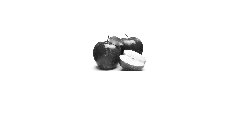

function im_mostreig = reduce_sampling(im, k)
    im_mostreig = im(1:k:end, 1:k:end);
end

figure;
imatge_mos = reduce_sampling(imatge_gris, 8);
imshow(imatge_mos);

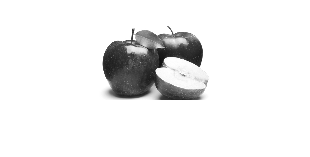

imatge_mos = reduce_sampling(imatge_gris, 4);
imshow(imatge_mos);

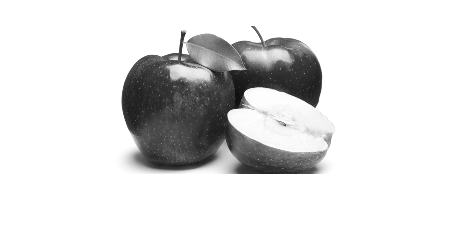

imatge_mos = reduce_sampling(imatge_gris, 2);
imshow(imatge_mos);

**Aplicació de soroll a Imatges:**

Afegeix els tres tipus de soroll dels disponibles a la imatge en escala de grisos (gaussian, `salt & pepper, poisson)`. 

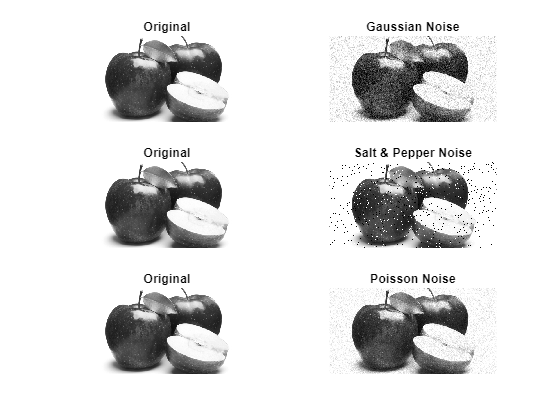

% Afegir soroll gaussià
imatge_gaussian = imnoise(imatge_gris, 'gaussian');

% Afegir soroll sal i pebre
imatge_salt_pepper = imnoise(imatge_gris, 'salt & pepper');

% Afegir soroll de Poisson
imatge_poisson = imnoise(imatge_gris, 'poisson');

figure;

% Original y Gauss
subplot(3,2,1);
imshow(imatge_gris);
title('Original');
subplot(3,2,2);
imshow(imatge_gaussian);
title('Gaussian Noise');

% Original y Salt & Pepper
subplot(3,2,3);
imshow(imatge_gris);
title('Original');
subplot(3,2,4);
imshow(imatge_salt_pepper);
title('Salt & Pepper Noise');

% Original y Poisson
subplot(3,2,5);
imshow(imatge_gris);
title('Original');
subplot(3,2,6);
imshow(imatge_poisson);
title('Poisson Noise');